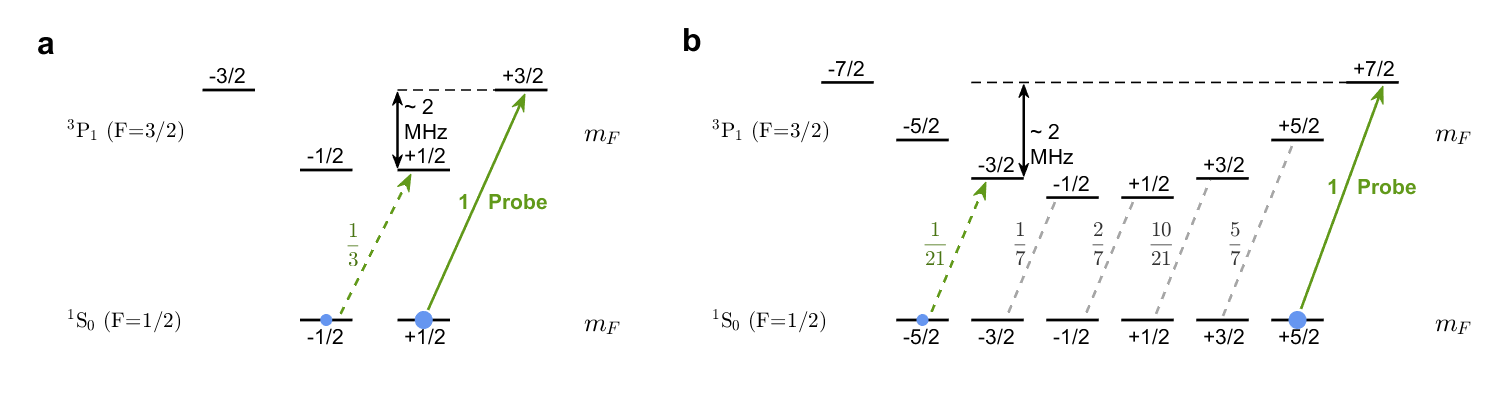


clear all;
close all;

xp = 1500;
yp = 400;
f1 = figure('Position', [100, 200, 1500, 400]);
hold on; axis off;
%axis([0 150 0 40]);
%set(gca,'XMinorGrid','on','YMinorGrid','on');
%set(gca,'Visible','off');
lw = 2;
fs = 16;
hw = 13;
hl = 13;
xlen = 0.035;
xbox = 0.04;
ybox = 0.077;
yab = 0.88;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% 171Yb %
xa = 0.02;
annotation(f1,'textbox',[xa yab xbox ybox],'String', 'a', ...
    'EdgeColor','none','FontName','times new roman','FontSize',fs*1.5,'FontWeight','bold');

x10 = 0.25-0.02+xa; xstep1 = 0.03;

% 1S0,1/2 %
y1 = 0.2;
for mF = -1/2:1:1/2
    annotation(f1,'line',[x10+(mF-1/2)*xlen+mF*xstep1 x10+(mF+1/2)*xlen+mF*xstep1], ...
        [y1 y1],'Color','k','LineWidth',lw);
    if sign(mF) > 0
        sign_m = '+';
    elseif sign(mF) < 0
        sign_m = '';
    end
    annotation(f1,'textbox',[x10+(mF-1/2)*xlen+mF*xstep1 y1-ybox xbox ybox], ...
        'String', [sign_m,num2str(mF*2,'%.0f'),'/2'], ...
        'EdgeColor','none','FontName','times new roman','FontSize',fs);
end

% 1/2,-1/2 %
rpixel1 = 6;
annotation(f1,'ellipse',[x10+(-1/2)*xlen+(-1/2)*xstep1-rpixel1/xp y1-rpixel1/yp ...
    2*rpixel1/xp 2*rpixel1/yp],'FaceColor',[0.40 0.59 0.94],'EdgeColor','none');
% 1/2,+1/2 %
rpixel2 = 9;
annotation(f1,'ellipse',[x10+(+1/2)*xlen+(+1/2)*xstep1-rpixel2/xp y1-rpixel2/yp ...
    2*rpixel2/xp 2*rpixel2/yp],'FaceColor',[0.40 0.59 0.94],'EdgeColor','none');


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% 3P1,3/2 %
y3 = 0.55; ystep3 = 0.025;
for mF = -3/2:1:3/2
    annotation(f1,'line',[x10+(mF-1/2)*xlen+mF*xstep1 x10+(mF+1/2)*xlen+mF*xstep1], ...
        [y3+(2*mF)^2*ystep3 y3+(2*mF)^2*ystep3],'Color','k','LineWidth',lw);
    if sign(mF) > 0
        sign_m = '+';
    elseif sign(mF) < 0
        sign_m = '';
    end
    annotation(f1,'textbox',[x10+(mF-1/2)*xlen+mF*xstep1 y3+(2*mF)^2*ystep3 xbox ybox], ...
        'String', [sign_m,num2str(mF*2,'%.0f'),'/2'], ...
        'EdgeColor','none','FontName','times new roman','FontSize',fs);
end


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% 虚线 %
annotation(f1,'line',[x10+(1/2-1/2)*xlen+1/2*xstep1 x10+(3/2-1/2)*xlen+3/2*xstep1], ...
    [y3+(2*3/2)^2*ystep3 y3+(2*3/2)^2*ystep3], ...
    'LineStyle','--','Color','k','LineWidth',0.6*lw);
% 双箭头 %
annotation(f1,'doublearrow',[x10+(1/2-1/2)*xlen+1/2*xstep1 x10+(1/2-1/2)*xlen+1/2*xstep1], ...
    [y3+(2*1/2)^2*ystep3+0.005 y3+(2*3/2)^2*ystep3-0.005], ...
    'LineStyle','-','Color','k','LineWidth',0.9*lw);
% ~2MHz %
annotation(f1,'textbox',[x10+(1/2-1/2)*xlen+1/2*xstep1 y3+(2*3/2)^2*ystep3-ybox ...
    1.5*xbox ybox], 'String', '~ 2 MHz', ...
    'EdgeColor','none','FontName','times new roman','FontSize',fs);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% -1/2 --- +1/2 %
annotation(f1,'arrow',[0.177 0.224]-0.2+x10,[0.2150 0.5650],'LineStyle','--', ...
    'Color',[0.38 0.60 0.10],'LineWidth',2,'HeadWidth',hw,'HeadLength',hl);
annotation(f1,'textbox',[x10+(-1/2-0.2)*xlen (y1+y3)/2 xbox ybox], ...
    'String','$$\frac{1}{3}$$','Interpreter','latex', ...
    'Color',[0.29 0.46 0.08],'EdgeColor','none', ...
    'FontName','times new roman','FontSize',fs,'FontWeight','bold');
% +1/2 --- +3/2 %
annotation(f1,'arrow',[0.2353 0.3000]-0.2+x10,[0.2250 0.7655],'LineStyle','-', ...
    'Color',[0.38 0.60 0.10],'LineWidth',2,'HeadWidth',hw,'HeadLength',hl);
annotation(f1,'textbox',[x10+(1/2+0.95)*xlen (y1+0.9*y3+3^2*ystep3)/2 3*xbox ybox], ...
    'String', '1   Probe','Color',[0.38 0.60 0.10],'EdgeColor','none', ...
    'FontName','times new roman','FontSize',fs,'FontWeight','bold');

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

deltax = 0.02;
xSP1 = xa+deltax;
% 1S0 %
y1S0 = y1-ybox/2;
annotation(f1,'textbox',[xSP1 y1S0 xbox*3 ybox], ...
    'interpreter','latex','String', '$\rm{^{1}S_0}$ (F=1/2)', ...
    'EdgeColor','none','FontName','times new roman','FontSize',fs);
% 3P1 %
y3P1 = y3+(1^2+3^2)/2*ystep3-ybox/2;
annotation(f1,'textbox',[xSP1 y3P1 xbox*3 ybox], ...
    'interpreter','latex','String', '$\rm{^{3}P_1}$ (F=3/2)', ...
    'EdgeColor','none','FontName','times new roman','FontSize',fs);

% mF %
deltaxm = 0.02;
xm1 = x10+(3/2+1/2)*xlen+3/2*xstep1 + deltaxm;
annotation(f1,'textbox',[xm1 y3P1 xbox ybox], ...
    'interpreter','latex','String', '$m_F$', ...
    'EdgeColor','none','FontName','times new roman','FontSize',fs*1.2);
annotation(f1,'textbox',[xm1 y1S0 xbox ybox], ...
    'interpreter','latex','String', '$m_F$', ...
    'EdgeColor','none','FontName','times new roman','FontSize',fs*1.2);


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% 173Yb %
xb = 0.45;
annotation(f1,'textbox',[xb yab xbox ybox],'String', 'b', ...
    'EdgeColor','none','FontName','times new roman','FontSize',fs*1.5,'FontWeight','bold');

x30 = 0.74-0.45+xb; xstep3 = 0.015;

% 1S0,5/2 %
y5 = y1;
for mF = -5/2:1:5/2
    annotation(f1,'line',[x30+(mF-1/2)*xlen+mF*xstep3 x30+(mF+1/2)*xlen+mF*xstep3], ...
        [y5 y5],'Color','k','LineWidth',lw);
    if sign(mF) > 0
        sign_m = '+';
    elseif sign(mF) < 0
        sign_m = '';
    end
    annotation(f1,'textbox',[x30+(mF-1/2)*xlen+mF*xstep3 y5-ybox xbox ybox], ...
        'String', [sign_m,num2str(mF*2,'%.0f'),'/2'], ...
        'EdgeColor','none','FontName','times new roman','FontSize',fs);
end

% 5/2,-5/2 %
rpixel3 = 6;
annotation(f1,'ellipse',[x30+(-5/2)*xlen+(-5/2)*xstep3-rpixel3/xp y5-rpixel3/yp ...
    2*rpixel3/xp 2*rpixel3/yp],'FaceColor',[0.40 0.59 0.94],'EdgeColor','none');
% 5/2,+5/2 %
rpixel4 = 9;
annotation(f1,'ellipse',[x30+(+5/2)*xlen+(+5/2)*xstep3-rpixel4/xp y5-rpixel4/yp ...
    2*rpixel4/xp 2*rpixel4/yp],'FaceColor',[0.40 0.59 0.94],'EdgeColor','none');


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% 3P1,7/2 %
y7 = 0.5; ystep7 = 0.006;
for mF = -7/2:1:7/2
    annotation(f1,'line',[x30+(mF-1/2)*xlen+mF*xstep3 x30+(mF+1/2)*xlen+mF*xstep3], ...
        [y7+(2*mF)^2*ystep7 y7+(2*mF)^2*ystep7],'Color','k','LineWidth',lw);
    if sign(mF) > 0
        sign_m = '+';
    elseif sign(mF) < 0
        sign_m = '';
    end
    annotation(f1,'textbox',[x30+(mF-1/2)*xlen+mF*xstep3 y7+(2*mF)^2*ystep7 xbox ybox], ...
        'String', [sign_m,num2str(mF*2,'%.0f'),'/2'], ...
        'EdgeColor','none','FontName','times new roman','FontSize',fs);
end


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% 虚线 %
annotation(f1,'line',[x30+(-3/2-1/2)*xlen-3/2*xstep3 x30+(7/2-1/2)*xlen+7/2*xstep3], ...
    [y7+(2*7/2)^2*ystep7 y7+(2*7/2)^2*ystep7], ...
    'LineStyle','--','Color','k','LineWidth',0.6*lw);
% 双箭头 %
annotation(f1,'doublearrow',[x30+(-3/2+1/2)*xlen-3/2*xstep3 x30+(-3/2+1/2)*xlen-3/2*xstep3], ...
    [y7+(2*-3/2)^2*ystep7+0.005 y7+(2*7/2)^2*ystep7-0.005], ...
    'LineStyle','-','Color','k','LineWidth',0.9*lw);
% ~2MHz %
annotation(f1,'textbox',[x30+(-3/2+1/2)*xlen-3/2*xstep3 y7+(7^2+3^2)*ystep7/2-ybox/2 ...
    1.5*xbox ybox], 'String', '~ 2 MHz', ...
    'EdgeColor','none','FontName','times new roman','FontSize',fs);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% -5/2 --- -3/2 %
annotation(f1,'arrow',[0.62100 0.65733]-0.45+xb,[0.22 0.545], ...
    'Color',[0.38 0.6 0.1],'LineStyle','--', ...
    'LineWidth',lw,'HeadWidth',hw,'HeadLength',hl);
annotation(f1,'textbox',[x30+(-5/2-1.2)*xlen (y1+y7+3^2*ystep7)/2 xbox ybox], ...
    'String','$$\frac{1}{21}$$','Interpreter','latex', ...
    'Color',[0.29 0.46 0.08],'EdgeColor','none', ...
    'FontName','times new roman','FontSize',fs,'FontWeight','bold');

% +5/2 --- +7/2 %
annotation(f1,'arrow',[0.86733 0.922]-0.45+xb,[0.2275 0.785], ...
    'Color',[0.38 0.6 0.1],'LineWidth',lw,'HeadWidth',hw,'HeadLength',hl);
annotation(f1,'textbox',[x30+(5/2+1.5)*xlen (y1+y7+7^2*ystep7)/2 3*xbox ybox], ...
    'String', '1   Probe','Color',[0.38 0.60 0.10],'EdgeColor','none', ...
    'FontName','times new roman','FontSize',fs,'FontWeight','bold');

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

yfrac = (y1+y7+3^2*ystep7)/2;
% -3/2 --- -1/2 %
annotation(f1,'line',[0.70333 0.67133]-0.45+xb,[0.495 0.21], ...
    'Color',[0.65 0.65 0.65],'LineStyle','--','LineWidth',lw);
annotation(f1,'textbox',[x30+(-3/2-0.5)*xlen yfrac xbox ybox], ...
    'String','$$\frac{1}{7}$$','Interpreter','latex', ...
    'Color',[0.2 0.2 0.2],'EdgeColor','none', ...
    'FontName','times new roman','FontSize',fs,'FontWeight','bold');

% -1/2 --- +1/2 %
annotation(f1,'line',[0.75533 0.72333]-0.45+xb,[0.495 0.21], ...
    'Color',[0.65 0.65 0.65],'LineStyle','--','LineWidth',lw);
annotation(f1,'textbox',[x30+(-1/2-0.0)*xlen yfrac xbox ybox], ...
    'String','$$\frac{2}{7}$$','Interpreter','latex', ...
    'Color',[0.2 0.2 0.2],'EdgeColor','none', ...
    'FontName','times new roman','FontSize',fs,'FontWeight','bold');

% +1/2 --- +3/2 %
annotation(f1,'line',[0.77067 0.80667]-0.45+xb,[0.215 0.55], ...
    'Color',[0.65 0.65 0.65],'LineStyle','--','LineWidth',lw);
annotation(f1,'textbox',[x30+(1/2+0.1)*xlen yfrac xbox ybox], ...
    'String','$$\frac{10}{21}$$','Interpreter','latex', ...
    'Color',[0.2 0.2 0.2],'EdgeColor','none', ...
    'FontName','times new roman','FontSize',fs,'FontWeight','bold');

% +3/2 --- +5/2 %
annotation(f1,'line',[0.86133 0.81533]-0.45+xb,[0.635 0.21], ...
    'Color',[0.65 0.65 0.65],'LineStyle','--','LineWidth',lw);
annotation(f1,'textbox',[x30+(3/2+0.6)*xlen yfrac xbox ybox], ...
    'String','$$\frac{5}{7}$$','Interpreter','latex', ...
    'Color',[0.2 0.2 0.2],'EdgeColor','none', ...
    'FontName','times new roman','FontSize',fs,'FontWeight','bold');


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

xSP1 = xb+deltax;
% 1S0 %
annotation(f1,'textbox',[xSP1 y1S0 xbox*3 ybox], ...
    'interpreter','latex','String', '$\rm{^{1}S_0}$ (F=1/2)', ...
    'EdgeColor','none','FontName','times new roman','FontSize',fs);
% 3P1 %
annotation(f1,'textbox',[xSP1 y3P1 xbox*3 ybox], ...
    'interpreter','latex','String', '$\rm{^{3}P_1}$ (F=3/2)', ...
    'EdgeColor','none','FontName','times new roman','FontSize',fs);

% mF %
xm3 = x30+(7/2+1/2)*xlen+7/2*xstep3 + deltaxm;
annotation(f1,'textbox',[xm3 y3P1 xbox ybox], ...
    'interpreter','latex','String', '$m_F$', ...
    'EdgeColor','none','FontName','times new roman','FontSize',fs*1.2);
annotation(f1,'textbox',[xm3 y1S0 xbox ybox], ...
    'interpreter','latex','String', '$m_F$', ...
    'EdgeColor','none','FontName','times new roman','FontSize',fs*1.2);


set(f1,'Visible','on');


savefig(f1,'D:\MATLAB_Git\MATLAB-atomic-calculation\Comag_Pub\Fig5\Fig5.fig');
saveas(f1,'D:\MATLAB_Git\MATLAB-atomic-calculation\Comag_Pub\Fig5\Fig5.png');
hgexport(f1,'D:\MATLAB_Git\MATLAB-atomic-calculation\Comag_Pub\Fig5\Fig5.eps');
% 
save('D:\MATLAB_Git\MATLAB-atomic-calculation\Comag_Pub\Fig5\Fig5.mat');

